%% Varme igennem finderne

t = 0.0005 % Tykkelse

t = 5.0000e-04


w = 46e-2 %Højde af finden

w = 0.4600


P = 2*w + 2*t % Wierd værdig men rigtig

P = 0.9210

 
T_inf = 293 .15 %Rum temperatur i kelvin

T_inf = 293.1500


L = 3e-2 %dybden af finden 

L = 0.0300


K = 177 % Konduktivitet for aluminium alloy 

K = 177


A_c = w*t %Udregenlses værdig 

A_c = 2.3000e-04


h = 10 % Fra tabel A.1 

h = 10


m = sqrt((h*P)/(K*A_c)) %Side 150 tabel 3.4  

m = 15.0411


syms x T

T_b = 37.5 + 273.15 

T_b = 310.6500


Phi_f = (cosh(m*(L-x)))/(cosh(m*L)) %Side 150 tabel 3.4 case B

$$Phi\_f = \frac{4503599627370496\,\cosh\left(\frac{4233690008966871\,x}{281474976710656}-\frac{12701070026900613}{28147497671065600}\right)}{4969923101164757}$$


T(x) = solve((T-T_inf)/(T_b-T_inf) == Phi_f, T) %Phit   sættes lig phi_f for at finde T til x 

$$T(x) = \frac{78812993478983680\,\cosh\left(\frac{4233690008966871\,x}{281474976710656}-\frac{12701070026900613}{28147497671065600}\right)}{4969923101164757}+\frac{5863}{20}$$


T = vpa(T(linspace(0, L, 100)), 5) - 273.15

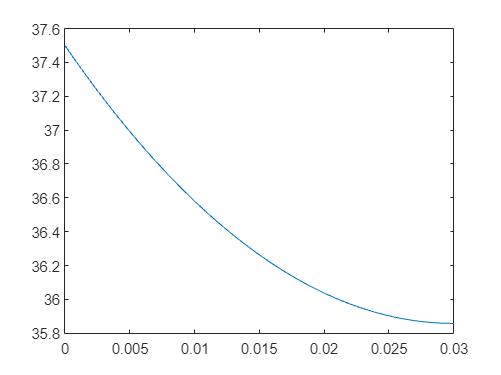


plot(linspace(0, L, 100), T)

clear


## Optimisering af afstand imellem finder

g = 9.82

g = 9.8200


T_s = linspace(30+273.15, 80+273.15, 500) %lincepsace over vores variende temperature

T_s =   303.1500  303.2502  303.3504  303.4506  303.5508  303.6510  303.7512  303.8514  303.9516  304.0518  304.1520  304.2522  304.3524  304.4526  304.5528  304.6530  304.7532  304.8534  304.9536  305.0538  305.1540  305.2542  305.3544  305.4546  305.5548  305.6550  305.7552  305.8554  305.9556  306.0558  306.1560  306.2562  306.3564  306.4566  306.5568  306.6570  306.7572  306.8574  306.9576  307.0578  307.1580  307.2582  307.3584  307.4586  307.5588  307.6590  307.7592  307.8594  307.9596  308.0598



T_inf = 20+273.15 %temperatur uden for radiator

T_inf = 293.1500

 
ny = linspace(15.52e-6, 17.88e-6, 500) %kinematisk viskositet 

ny = 1.0e-04 *

    0.1552    0.1552    0.1553    0.1553    0.1554    0.1554    0.1555    0.1555    0.1556    0.1556    0.1557    0.1557    0.1558    0.1558    0.1559    0.1559    0.1560    0.1560    0.1561    0.1561    0.1561    0.1562    0.1562    0.1563    0.1563    0.1564    0.1564    0.1565    0.1565    0.1566    0.1566    0.1567    0.1567    0.1568    0.1568    0.1569    0.1569    0.1569    0.1570    0.1570    0.1571    0.1571    0.1572    0.1572    0.1573    0.1573    0.1574    0.1574    0.1575    0.1575



ny_f = polyfit([30, 40, 50, 60, 70, 80] , [16.26e-6, 17.23e-6, 18.21e-6, 19.22e-6, 20.25e-6, 21.3e-6], 2);

ny = polyval(ny_f, linspace(30, 80, 500)) %bare for sjov høhø 

ny = 1.0e-04 *

    0.1626    0.1627    0.1628    0.1629    0.1630    0.1631    0.1632    0.1633    0.1634    0.1635    0.1636    0.1637    0.1638    0.1639    0.1640    0.1641    0.1641    0.1642    0.1643    0.1644    0.1645    0.1646    0.1647    0.1648    0.1649    0.1650    0.1651    0.1652    0.1653    0.1654    0.1655    0.1656    0.1657    0.1658    0.1659    0.1660    0.1661    0.1662    0.1663    0.1664    0.1665    0.1666    0.1666    0.1667    0.1668    0.1669    0.1670    0.1671    0.1672    0.1673



T_stoff = (T_s + T_inf)/2. %Temperature for at finde stoff værdiger 

T_stoff =   298.1500  298.2001  298.2502  298.3003  298.3504  298.4005  298.4506  298.5007  298.5508  298.6009  298.6510  298.7011  298.7512  298.8013  298.8514  298.9015  298.9516  299.0017  299.0518  299.1019  299.1520  299.2021  299.2522  299.3023  299.3524  299.4025  299.4526  299.5027  299.5528  299.6029  299.6530  299.7031  299.7532  299.8033  299.8534  299.9035  299.9536  300.0037  300.0538  300.1039  300.1540  300.2041  300.2542  300.3043  300.3544  300.4045  300.4546  300.5047  300.5548  300.6049



beta = 1./T_stoff % Beta

beta =     0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0034    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033    0.0033



S = 0.02 %Start afstand imellem finderne, Udgår via division så den betyde ikke nået

S = 0.0200


alpha = linspace(22.5e-6, 27e-6, 500) %luft stuff værdig. 

alpha = 1.0e-04 *

    0.2250    0.2251    0.2252    0.2253    0.2254    0.2255    0.2255    0.2256    0.2257    0.2258    0.2259    0.2260    0.2261    0.2262    0.2263    0.2264    0.2264    0.2265    0.2266    0.2267    0.2268    0.2269    0.2270    0.2271    0.2272    0.2273    0.2273    0.2274    0.2275    0.2276    0.2277    0.2278    0.2279    0.2280    0.2281    0.2282    0.2282    0.2283    0.2284    0.2285    0.2286    0.2287    0.2288    0.2289    0.2290    0.2291    0.2291    0.2292    0.2293    0.2294



Ra_s = (g.*beta.*(T_s-T_inf).*S^3) ./ (ny.*alpha)

Ra_s = 1.0e+04 *

    0.7202    0.7265    0.7329    0.7392    0.7456    0.7519    0.7582    0.7645    0.7707    0.7770    0.7832    0.7894    0.7956    0.8018    0.8080    0.8142    0.8203    0.8265    0.8326    0.8387    0.8448    0.8508    0.8569    0.8629    0.8690    0.8750    0.8810    0.8870    0.8930    0.8989    0.9048    0.9108    0.9167    0.9226    0.9285    0.9343    0.9402    0.9460    0.9519    0.9577    0.9635    0.9693    0.9750    0.9808    0.9865    0.9923    0.9980    1.0037    1.0094    1.0151


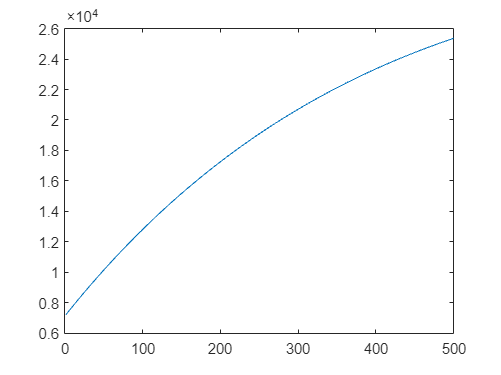


plot(Ra_s)


L = 0.48

L = 0.4800


Sopt = 2.71.*(Ra_s./(S^3 .* L)).^(-1/4)

Sopt =     0.0130    0.0130    0.0130    0.0129    0.0129    0.0129    0.0129    0.0128    0.0128    0.0128    0.0128    0.0127    0.0127    0.0127    0.0127    0.0126    0.0126    0.0126    0.0126    0.0125    0.0125    0.0125    0.0125    0.0124    0.0124    0.0124    0.0124    0.0124    0.0123    0.0123    0.0123    0.0123    0.0123    0.0122    0.0122    0.0122    0.0122    0.0122    0.0121    0.0121    0.0121    0.0121    0.0121    0.0121    0.0120    0.0120    0.0120    0.0120    0.0120    0.0120


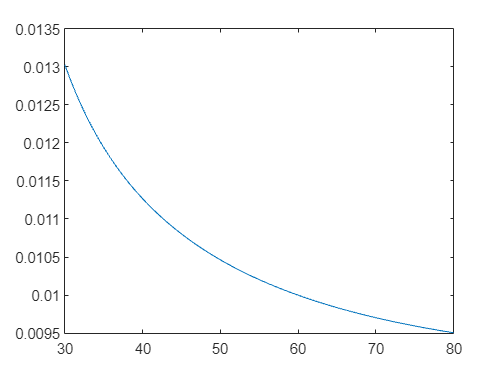


plot(T_s-273.15, Sopt)


fx = polyfit(T_s, Sopt, 2)

fx =     0.0000   -0.0011    0.1978



S_opt_30T = polyval(fx, 37.5+273.15)

S_opt_30T = 0.0117